data=csvread("result/ModelingResults.csv",1);

bitflip_data = data(data(:,8)==0,:);
depol_data = data(data(:,8)==1,:);
damping_data = data(data(:,8)==3,:);

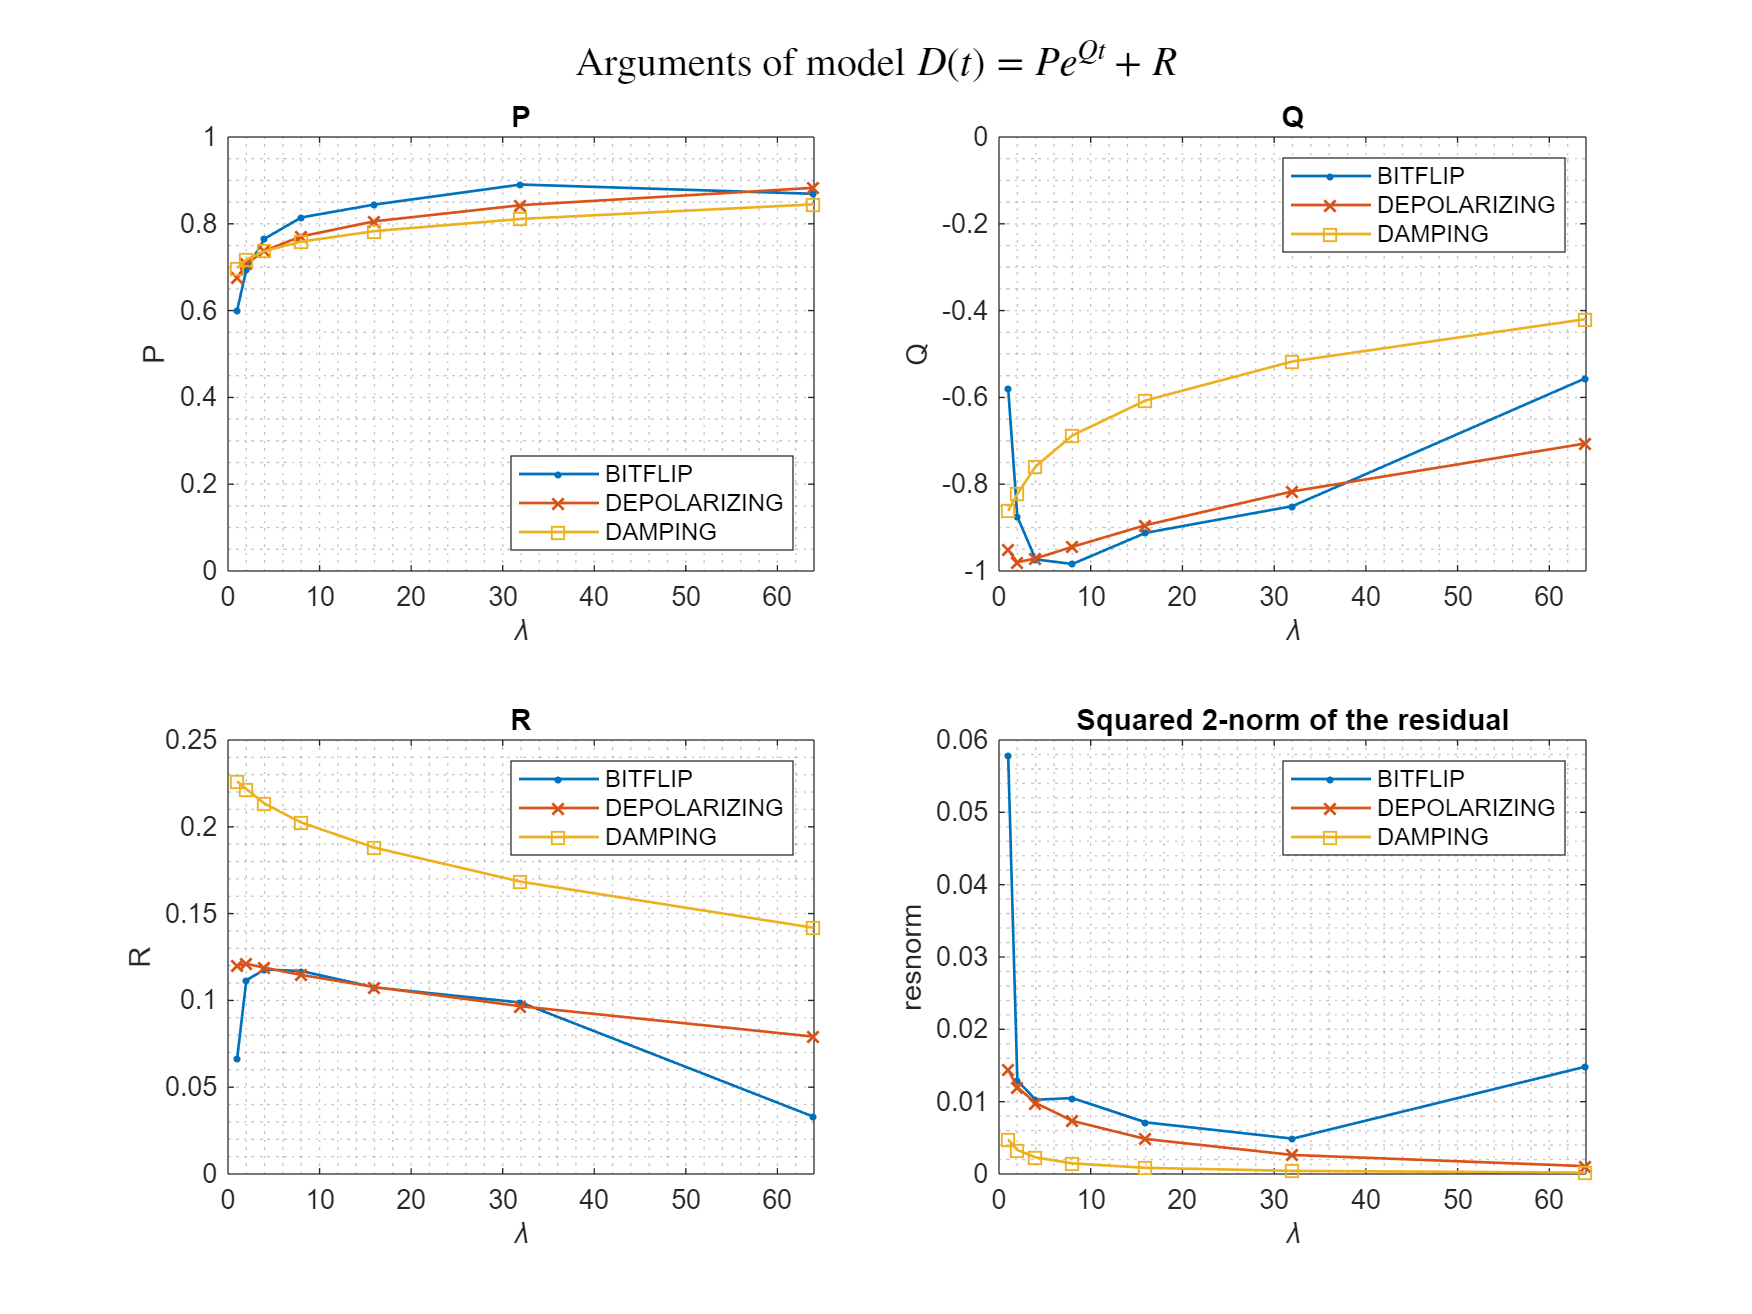

figure(Position=[0,0,1024,768]); 
sgtitle("Arguments of model $D(t)=Pe^{Qt}+R$", 'interpreter','latex')
%%%%%%%%%% P-lambda
subplot(2,2,1); hold on;
title('P');
xlabel('\lambda'); ylabel('P');
ylim([0,1]);
legend(Location="southeast");
box on; grid minor;

plot(bitflip_data(:,3), bitflip_data(:,10),Marker="." ,DisplayName='BITFLIP',MarkerSize=8, LineWidth=1);
plot(depol_data(:,3), depol_data(:,10),Marker="x",DisplayName='DEPOLARIZING',MarkerSize=6, LineWidth=1);
plot(damping_data(:,3), damping_data(:,10),Marker="square",DisplayName='DAMPING',MarkerSize=6, LineWidth=1);

%%%%%%%%%% Q-lambda
subplot(2,2,2); hold on;
title('Q');
xlabel('\lambda'); ylabel('Q');
ylim([-1,0]);
legend(Location="northeast");
box on; grid minor;

plot(bitflip_data(:,3), bitflip_data(:,11),Marker="." ,DisplayName='BITFLIP',MarkerSize=8, LineWidth=1);
plot(depol_data(:,3), depol_data(:,11),Marker="x",DisplayName='DEPOLARIZING',MarkerSize=6, LineWidth=1);
plot(damping_data(:,3), damping_data(:,11),Marker="square",DisplayName='DAMPING',MarkerSize=6, LineWidth=1);

%%%%%%%%%% R-lambda
subplot(2,2,3); hold on;
title('R');
xlabel('\lambda'); ylabel('R');
legend(Location="northeast");
box on; grid minor;

plot(bitflip_data(:,3), bitflip_data(:,12),Marker="." ,DisplayName='BITFLIP',MarkerSize=8, LineWidth=1);
plot(depol_data(:,3), depol_data(:,12),Marker="x",DisplayName='DEPOLARIZING',MarkerSize=6, LineWidth=1);
plot(damping_data(:,3), damping_data(:,12),Marker="square",DisplayName='DAMPING',MarkerSize=6, LineWidth=1);

%%%%%%%%%% resnorm-lambda
subplot(2,2,4); hold on;
title('Squared 2-norm of the residual');
xlabel('\lambda'); ylabel('resnorm');
legend(Location="northeast");
box on; grid minor;

plot(bitflip_data(:,3), bitflip_data(:,13),Marker="." ,DisplayName='BITFLIP',MarkerSize=8, LineWidth=1);
plot(depol_data(:,3), depol_data(:,13),Marker="x",DisplayName='DEPOLARIZING',MarkerSize=6, LineWidth=1);
plot(damping_data(:,3), damping_data(:,13),Marker="square",DisplayName='DAMPING',MarkerSize=6, LineWidth=1);